%Начало обработки по 3 параметрам

rho_brain_min = 1/0.717;
rho_brain_max = 1/0.066;	
rho_skin_min = 1/0.726;	
rho_skin_max = 1/0.024;	
rho_scull_min = 1/0.2; 
rho_scull_max = 1/0.002; 

rho_skin = rho_skin_min:(rho_skin_max - rho_skin_min)/9:rho_skin_max;
rho_scull = rho_scull_min:(rho_scull_max - rho_scull_min)/9:rho_scull_max;
rho_brain = rho_brain_min:(rho_brain_max - rho_brain_min)/9:rho_brain_max;

%Деление на подмассивы
data_br_big = {};
data_fh_big = {};
data_fh_small = {};
data_fh_micro = {};
j = 1;
for i=1:length(rho_brain):length(imp_fh_small)
    data_br_big{j} = imp_brain_big(i:(i+length(rho_brain)-1));
    data_fh_big{j} = imp_fh_big(i:(i+length(rho_brain)-1));
    data_fh_small{j} = imp_fh_small(i:(i+length(rho_brain)-1));
    data_fh_micro{j} = imp_fh_micro(i:(i+length(rho_brain)-1));
    j = j+1;
end

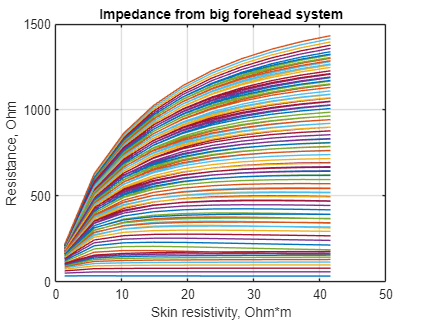

%Построение графиков от ро кожи
for i=1:1:(length(data_fh_micro)/1)
    plot(rho_skin,data_fh_big{i})
    hold on
end
grid on
title("Impedance from big forehead system")
xlabel("Skin resistivity, Ohm*m")
ylabel("Resistance, Ohm")
hold off

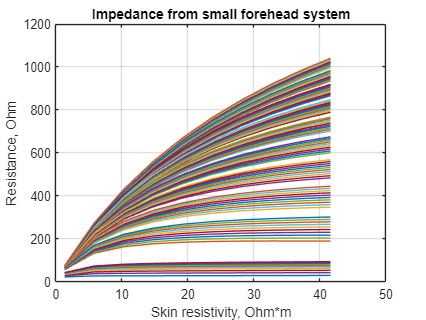

for i=1:1:(length(data_fh_micro)/1)
    plot(rho_skin,data_fh_small{i})
    hold on
end
grid on
title("Impedance from small forehead system")
xlabel("Skin resistivity, Ohm*m")
ylabel("Resistance, Ohm")
hold off

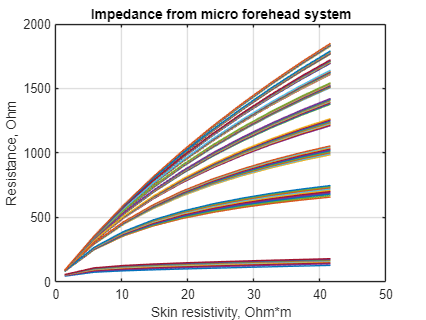

for i=1:1:(length(data_fh_micro)/1)
    plot(rho_skin,data_fh_micro{i})
    hold on
end
grid on
title("Impedance from micro forehead system")
xlabel("Skin resistivity, Ohm*m")
ylabel("Resistance, Ohm")
hold off

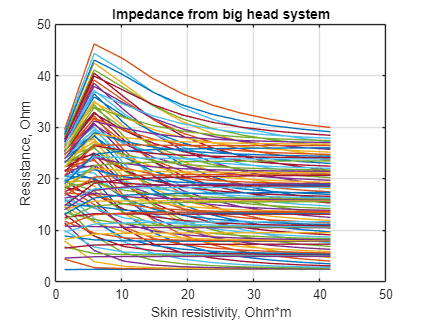

for i=1:1:(length(data_fh_micro)/1)
    plot(rho_skin,data_br_big{i})
    hold on
end
grid on
title("Impedance from big head system")
xlabel("Skin resistivity, Ohm*m")
ylabel("Resistance, Ohm")
hold off

%Подбор аппроксимации через curve fitting
d_fh_big = data_fh_big{length(data_fh_micro)/2};
d_br_big = data_br_big{length(data_fh_micro)/2};
d_fh_small = data_fh_small{length(data_fh_micro)/2};
d_fh_micro = data_fh_micro{length(data_fh_micro)/2};

%Работаем с суммой двух экспонент
c_br_big = {};
c_fh_big = {};
c_fh_small = {};
c_fh_micro = {};
for i = 1:1:length(data_br_big)
    c_br_big{i} = coeffvalues(fit(transpose(rho_skin),data_br_big{i},'exp2'));
    c_fh_big{i} = coeffvalues(fit(transpose(rho_skin),data_fh_big{i},'exp2'));
    c_fh_small{i} = coeffvalues(fit(transpose(rho_skin),data_fh_small{i},'exp2'));
    c_fh_micro{i} = coeffvalues(fit(transpose(rho_skin),data_fh_micro{i},'exp2'));
end

%Увеличение количества точек для анализа
rho_skin1 = rho_skin_min:(rho_skin_max-rho_skin_min)/10000:rho_skin_max;
db_br_big = {};
db_fh_big = {};
db_fh_small = {};
db_fh_micro = {};
for i = 1:1:length(data_br_big)
    db_br_big{i} = exp2(rho_skin1,c_br_big{i});
    db_fh_big{i} = exp2(rho_skin1,c_fh_big{i});
    db_fh_small{i} = exp2(rho_skin1,c_fh_small{i});
    db_fh_micro{i} = exp2(rho_skin1,c_fh_micro{i});
end

% Опорные значения базового импеданса
base_br_big = 60.7; % В Ом
base_fh_big = 125.6;
base_fh_small = 72.6;
base_fh_micro = 130; % Взято с меня

% Подбор интересующих точек
eps = 0.1;

points_br_big = {};
points_scull_br_big = [];
p_br_big = [];
points_brain_br_big = [];


points_fh_big = {};
points_scull_fh_big = [];
p_fh_big = [];
points_brain_fh_big = [];

points_fh_small = {};
points_scull_fh_small = [];
p_fh_small = [];
points_brain_fh_small = [];

points_fh_micro = {};
points_scull_fh_micro = [];
p_fh_micro = [];
points_brain_fh_micro = [];


for i = 1:1:length(data_br_big)
    points_br_big{i} = find(abs(db_br_big{i} - base_br_big)<eps);
    if (~isnan(points_br_big{i}))
        for j = 1:1:length(points_br_big{i})
            if (mod(i,10) == 0)
                k = 10;
            else
                k = mod(i,10);
            end
            if (mod(floor(i/10)+1,10) == 0)
                l = 10;
            elseif (mod(i,10) == 0)
                l = i/10;
            else
                l = mod(floor(i/10)+1,10);
            end
            points_scull_br_big = [points_scull_br_big rho_scull(k)];
            points_brain_br_big = [points_brain_br_big rho_brain(l)];
            p_br_big = [p_br_big rho_skin1(points_br_big{i}(j))];
        end
    end

    points_fh_big{i} = find(abs(db_fh_big{i} - base_fh_big)<eps);
    if (~isnan(points_fh_big{i}))
        for j = 1:1:length(points_fh_big{i})
                        if (mod(i,10) == 0)
                k = 10;
            else
                k = mod(i,10);
            end
            if (mod(floor(i/10)+1,10) == 0)
                l = 10;
            elseif (mod(i,10) == 0)
                l = i/10;
            else
                l = mod(floor(i/10)+1,10);
            end
            points_scull_fh_big = [points_scull_fh_big rho_scull(k)];
            points_brain_fh_big = [points_brain_fh_big rho_brain(l)];
            p_fh_big = [p_fh_big rho_skin1(points_fh_big{i}(j))];
        end
    end

    points_fh_small{i} = find(abs(db_fh_small{i} - base_fh_small)<eps);
    if (~isnan(points_fh_small{i}))
        for j = 1:1:length(points_fh_small{i})
                        if (mod(i,10) == 0)
                k = 10;
            else
                k = mod(i,10);
            end
            if (mod(floor(i/10)+1,10) == 0)
                l = 10;
            elseif (mod(i,10) == 0)
                l = i/10;
            else
                l = mod(floor(i/10)+1,10);
            end
            points_scull_fh_small = [points_scull_fh_small rho_scull(k)];
            points_brain_fh_small = [points_brain_fh_small rho_brain(l)];
            p_fh_small = [p_fh_small rho_skin1(points_fh_small{i}(j))];
        end
    end

    points_fh_micro{i} = find(abs(db_fh_micro{i} - base_fh_micro)<eps);
        if (~isnan(points_fh_micro{i}))
        for j = 1:1:length(points_fh_micro{i})
            if (mod(i,10) == 0)
                k = 10;
            else
                k = mod(i,10);
            end
            if (mod(floor(i/10)+1,10) == 0)
                l = 10;
            elseif (mod(i,10) == 0)
                l = i/10;
            else
                l = mod(floor(i/10)+1,10);
            end
            points_scull_fh_micro = [points_scull_fh_micro rho_scull(k)];
            points_brain_fh_micro = [points_brain_fh_micro rho_brain(l)];
            p_fh_micro = [p_fh_micro rho_skin1(points_fh_micro{i}(j))];
        end
    end
end

plot3(p_fh_small,points_scull_fh_small, points_brain_fh_small, LineWidth=3)
hold on
plot3(p_fh_big,points_scull_fh_big, points_brain_fh_big, LineWidth=3)
plot3(p_fh_micro,points_scull_fh_micro, points_brain_fh_micro, LineWidth=3)
plot3(p_br_big,points_scull_br_big, points_brain_br_big, LineWidth=3)
hold off
legend(["fh small" "fh big" "fh micro" "br big"])

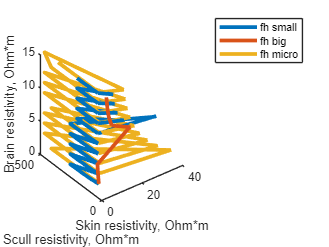

xlabel("Skin resistivity, Ohm*m")
ylabel("Scull resistivity, Ohm*m")
zlabel("Brain resistivity, Ohm*m")

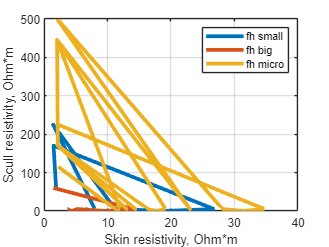

plot(p_fh_small,points_scull_fh_small, LineWidth=3)
hold on
plot(p_fh_big,points_scull_fh_big, LineWidth=3)
plot(p_fh_micro,points_scull_fh_micro, LineWidth=3)
hold off
grid on
legend(["fh small" "fh big" "fh micro"])
xlabel("Skin resistivity, Ohm*m")
ylabel("Scull resistivity, Ohm*m")

i1 = 1;
i2 = 1;
i3 = 1;
i4 = 1;
for i = 1:1:length(data_br_big)
    
end


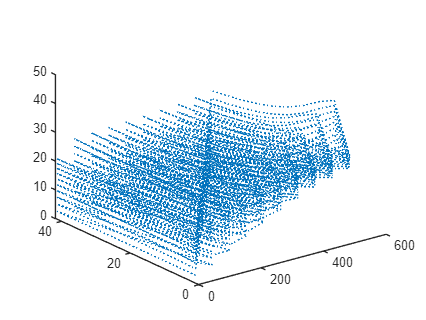

%Тестовое построение 3-хмерного массива
plot3(rho_scull0,rho_skin0,imp_brain_big,LineStyle=":")

%Конец обработки по 3 параметрам

data = data_big_close{1}

data =    45.3071   45.3070   45.3069   45.3068   45.3067   45.3066   45.3065   45.3064   45.3063   45.3062   45.3060   45.3059   45.3058   45.3057   45.3056   45.3055   45.3054   45.3053   45.3052   45.3051   45.3050   45.3049   45.3048   45.3047   45.3046   45.3045   45.3044   45.3042   45.3041   45.3040   45.3039   45.3038   45.3037   45.3036   45.3035   45.3034   45.3033   45.3032   45.3031   45.3030   45.3029   45.3028   45.3027   45.3026   45.3024   45.3023   45.3022   45.3021   45.3020   45.3019


data1 = data_to_analysis_far{1}

data1 =    97.6599
   97.9805
   98.2938
   98.5992
   98.8982
   99.1917
   99.4800
   99.7627
  100.0386
  100.3112


data_to_analysis_far = {}


data_to_analysis_far =

  0×0 empty cell array



data_to_analysis_close = {}


data_to_analysis_close =

  0×0 empty cell array



for i = 1:31:(217-31+1)
    data_to_analysis_far{(round(i/31)+1)} = imp_far(i:(i+30))
    data_to_analysis_close{(round(i/31)+1)} = imp_close(i:(i+30))
end

data_to_analysis_far = 1×1 cell array
    {31×1 double}


data_to_analysis_close = 1×1 cell array
    {31×1 double}


data_to_analysis_far = 1×2 cell array
    {31×1 double}    {31×1 double}


data_to_analysis_close = 1×2 cell array
    {31×1 double}    {31×1 double}


data_to_analysis_far = 1×3 cell array
    {31×1 double}    {31×1 double}    {31×1 double}


data_to_analysis_close = 1×3 cell array
    {31×1 double}    {31×1 double}    {31×1 double}


data_to_analysis_far = 1×4 cell array
    {31×1 double}    {31×1 double}    {31×1 double}    {31×1 double}


data_to_analysis_close = 1×4 cell array
    {31×1 double}    {31×1 double}    {31×1 double}    {31×1 double}


data_to_analysis_far = 1×5 cell array
    {31×1 double}    {31×1 double}    {31×1 double}    {31×1 double}    {31×1 double}


data_to_analysis_close = 1×5 cell array
    {31×1 double}    {31×1 double}    {31×1 double}    {31×1 double}    {31×1 double}


data_to_analysis_far = 1×6 cell array
    {31×1 double}    {31×1 double}    {31×1 double}    {31×1 double}    {31×1 double}    {31×1 double}


data_to_analysis_close = 1×6 cell array
    {31×1 double}    {31×1 double}    {31×1 double}    {31×1 double}    {31×1 double}    {31×1 double}


data_to_analysis_far = 1×7 cell array
    {31×1 double}    {31×1 double}    {31×1 double}    {31×1 double}    {31×1 double}    {31×1 double}    {31×1 double}


data_to_analysis_close = 1×7 cell array
    {31×1 double}    {31×1 double}    {31×1 double}    {31×1 double}    {31×1 double}    {31×1 double}    {31×1 double}


fit_coeffs_far = {};
fit_coeffs_close = {};
for i = 1:1:7
    fit_coeffs_far{i} = coeffvalues(fit(transpose(rho_scull),data_to_analysis_far{i},'exp2'));
    fit_coeffs_close{i} = coeffvalues(fit(transpose(rho_scull),data_to_analysis_close{i},'exp2'));
end

x = 50:0.0005:90;
data_big_far = {}


data_big_far =

  0×0 empty cell array



data_big_close = {}


data_big_close =

  0×0 empty cell array



for i = 1:1:7
    data_big_far{i} = fit_coeffs_far{i}(1)*exp(fit_coeffs_far{i}(2)*x)+fit_coeffs_far{i}(3)*exp(fit_coeffs_far{i}(4)*x);
    data_big_close{i} = fit_coeffs_close{i}(1)*exp(fit_coeffs_close{i}(2)*x)+fit_coeffs_close{i}(3)*exp(fit_coeffs_close{i}(4)*x);
end

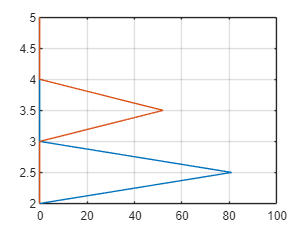

eps = 0.1;
rho_skin_fin_far = zeros(1,7);
rho_skin_fin_close = zeros(1,7);
for i = 1:1:7
    ind_far = find(abs(data_big_far{i} - 125.6)<eps);
    if (~isnan(ind_far))
    rho_skin_fin_far(i) = x(ind_far(1));
    end

    ind_close = find(abs(data_big_close{i} - 72.6)<eps);
    if (~isnan(ind_close))
    rho_skin_fin_close(i) = x(ind_close(1));
    end
     
end
plot(rho_skin_fin_far,rho_skin,rho_skin_fin_close,rho_skin)
grid on

xx = 2:0.0005:5

xx =     2.0000    2.0005    2.0010    2.0015    2.0020    2.0025    2.0030    2.0035    2.0040    2.0045    2.0050    2.0055    2.0060    2.0065    2.0070    2.0075    2.0080    2.0085    2.0090    2.0095    2.0100    2.0105    2.0110    2.0115    2.0120    2.0125    2.0130    2.0135    2.0140    2.0145    2.0150    2.0155    2.0160    2.0165    2.0170    2.0175    2.0180    2.0185    2.0190    2.0195    2.0200    2.0205    2.0210    2.0215    2.0220    2.0225    2.0230    2.0235    2.0240    2.0245


coef_far = coeffvalues(fit(transpose(rho_skin_fin_far),transpose(rho_scull),'exp2'))

coef_far =    77.5000         0         0         0


coef_close = coeffvalues(fit(transpose(rho_skin_fin_close),transpose(rho_scull),'exp1'))

coef_close = 1.0e+04 *

    4.1898   -0.0002


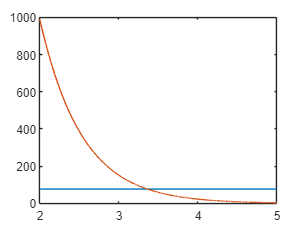

f_far = coef_far(1)*exp(coef_far(2)*xx)+coef_far(3)*exp(coef_far(4)*xx);
f_close = coef_close(1)*exp(coef_close(2)*xx);

plot(xx,f_far,xx,f_close)

eps1 = 0.1;
intersection = find(abs(f_far-f_close) < eps1)

intersection =         2721        2722


f_close(intersection)

ans =    77.5341   77.4615


xx(intersection)

ans =     3.3600    3.3605


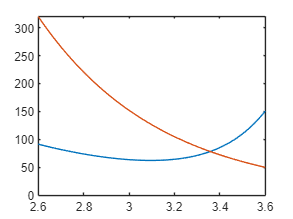

%far 
%       a =        2299  (-1822, 6421)
 %      b =      -1.248  (-1.996, -0.501)
  %     c =   1.774e-05  (-0.000952, 0.0009874)
   %    d =        4.38  (-13.15, 21.91)


%close
%       a =           0
 %      b =      -43.68
  %     c =   4.075e+04  (2.54e+04, 5.61e+04)
   %    d =      -1.864  (-1.976, -1.753)

f_far = 2299*exp(-1.248*xx)+1.774e-05*exp(4.38*xx);
f_close = 0*exp(-43.68*xx)+4.075e+04*exp(-1.864*xx);
plot(xx,f_far,xx,f_close)

x1 = [2.68, 2.938, 3.4271, 4.9141, 35]

x1 =     2.6800    2.9380    3.4271    4.9141   35.0000


y1 = [200, 150, 100, 50, 10]

y1 =    200   150   100    50    10


x2 = [3.3326, 3.4724, 3.7397, 4.5037, 9.8181]

x2 =     3.3326    3.4724    3.7397    4.5037    9.8181


%Секция функций. НЕ ТРОГАТЬ
% Работаем, как всегда, с суммой двух экспонент

function res = exp2(arr,coeffs)
    res = coeffs(1)*exp(coeffs(2)*arr)+ coeffs(3)*exp(coeffs(4)*arr);
end